%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312




%plotting the original waveform\

t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


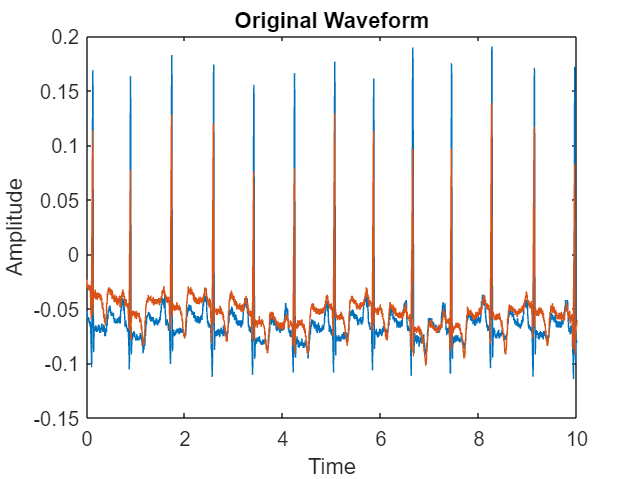

plot(t_og,a_cut)
title("Original Waveform")
xlabel("Time")
ylabel("Amplitude")



%changing the stereo wav file into a mono stream
a_cut_mono=reshape(a_cut,[],1)

a_cut_mono =    -0.0527
   -0.0537
   -0.0557
   -0.0586
   -0.0586
   -0.0615
   -0.0596
   -0.0586
   -0.0576
   -0.0586




%padding zeros to make a square matrix

sq_wave = [a_cut_mono,zeros(7200,7199)]

sq_wave =    -0.0527         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0537         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         


%generating a random key
key=rand(size(sq_wave))

key =     0.0845    0.1199    0.8140    0.3196    0.4824    0.7107    0.2987    0.4227    0.8361    0.9309    0.0296    0.7689    0.9499    0.1012    0.6718    0.8139    0.8685    0.2462    0.5326    0.9519    0.7764    0.9261    0.1271    0.6752    0.8184    0.3949    0.8155    0.0749    0.9076    0.3087    0.1658    0.5208    0.8900    0.3612    0.9153    0.4105    0.3155    0.3633    0.6347    0.8134    0.2373    0.3950    0.6240    0.3420    0.2215    0.9679    0.2115    0.5287    0.2027    0.9718
    0.8110    0.7258    0.0520    0.3673    0.2312    0.0890    0.9526    0.6931    0.8073    0.9864    0.4034    0.6005    0.0901    0.6260    0.2575    0.2287    0.4549    0.0596    0.1943    0.3018    0.1044    0.3678    0.0668    0.8645    0.1742    0.2003    0.9780    0.6859    0.1555    0.5831    0.3617    0.8851    0.0522    0.7072    0.0795    0.1777    0.7933    0.1542    0.3498    0.5557    0.9159    0.9868    0.4401    0.5278    0.7300    0.5449    0.6192    0.5199    0.5404   


%encryption
enc=sq_wave*key

enc =    -0.0045   -0.0063   -0.0429   -0.0169   -0.0254   -0.0375   -0.0158   -0.0223   -0.0441   -0.0491   -0.0016   -0.0405   -0.0501   -0.0053   -0.0354   -0.0429   -0.0458   -0.0130   -0.0281   -0.0502   -0.0409   -0.0488   -0.0067   -0.0356   -0.0432   -0.0208   -0.0430   -0.0039   -0.0479   -0.0163   -0.0087   -0.0275   -0.0469   -0.0190   -0.0483   -0.0216   -0.0166   -0.0192   -0.0335   -0.0429   -0.0125   -0.0208   -0.0329   -0.0180   -0.0117   -0.0510   -0.0112   -0.0279   -0.0107   -0.0512
   -0.0045   -0.0064   -0.0437   -0.0172   -0.0259   -0.0382   -0.0160   -0.0227   -0.0449   -0.0500   -0.0016   -0.0413   -0.0510   -0.0054   -0.0361   -0.0437   -0.0466   -0.0132   -0.0286   -0.0511   -0.0417   -0.0497   -0.0068   -0.0363   -0.0440   -0.0212   -0.0438   -0.0040   -0.0487   -0.0166   -0.0089   -0.0280   -0.0478   -0.0194   -0.0492   -0.0220   -0.0169   -0.0195   -0.0341   -0.0437   -0.0127   -0.0212   -0.0335   -0.0184   -0.0119   -0.0520   -0.0114   -0.0284   -0.0109   

enc_col=enc(:,1)

enc_col =    -0.0045
   -0.0045
   -0.0047
   -0.0050
   -0.0050
   -0.0052
   -0.0050
   -0.0050
   -0.0049
   -0.0050



enc_col=abs(enc_col)

enc_col =     0.0045
    0.0045
    0.0047
    0.0050
    0.0050
    0.0052
    0.0050
    0.0050
    0.0049
    0.0050


a_row=enc_col'

a_row =     0.0045    0.0045    0.0047    0.0050    0.0050    0.0052    0.0050    0.0050    0.0049    0.0050    0.0052    0.0051    0.0051    0.0050    0.0050    0.0050    0.0052    0.0054    0.0053    0.0053    0.0053    0.0054    0.0056    0.0055    0.0054    0.0052    0.0053    0.0057    0.0061    0.0065    0.0070    0.0073    0.0077    0.0084    0.0088    0.0080    0.0061    0.0039    0.0015    0.0017    0.0062    0.0108    0.0135    0.0143    0.0121    0.0074    0.0010    0.0045    0.0071    0.0076



%reshaping and converting the matrix into a png image
a_square=reshape(a_row,[100,72])

a_square =     0.0045    0.0061    0.0052    0.0059    0.0064    0.0051    0.0054    0.0059    0.0049    0.0054    0.0063    0.0050    0.0059    0.0069    0.0059    0.0061    0.0070    0.0053    0.0061    0.0064    0.0050    0.0059    0.0063    0.0052    0.0057    0.0068    0.0056    0.0066    0.0050    0.0037    0.0063    0.0048    0.0050    0.0062    0.0057    0.0050    0.0020    0.0036    0.0036    0.0038    0.0059    0.0037    0.0033    0.0051    0.0035    0.0034    0.0050    0.0040    0.0044    0.0057
    0.0045    0.0060    0.0053    0.0057    0.0066    0.0054    0.0054    0.0059    0.0051    0.0055    0.0060    0.0052    0.0058    0.0068    0.0058    0.0059    0.0071    0.0055    0.0059    0.0062    0.0052    0.0035    0.0062    0.0055    0.0072    0.0068    0.0054    0.0064    0.0049    0.0039    0.0063    0.0047    0.0049    0.0059    0.0054    0.0051    0.0025    0.0034    0.0037    0.0040    0.0056    0.0037    0.0035    0.0053    0.0038    0.0037    0.0049    0.0043    0.00

imwrite(a_square,'C:\Users\pooja\Desktop\Cryptography\hillcipher_wave_png.png')

%reading the png image and converting the pixel values to doubles
a_png=imread('C:\Users\pooja\Desktop\Cryptography\hillcipher_wave_png.png')

a_png = 100×72 uint8 matrix
   1   2   1   1   2   1   1   2   1   1   2   1   1   2   1   2   2   1   2   2   1   1   2   1   1   2   1   2   1   1   2   1   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   2   1   1   2   1   1   1   1   1   2   1   1   2   1   2   2   1   1   2   1   1   2   1   2   2   1   2   1   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   2   1   1   1   1   1   1   1   1   2   1   2   2   1   2   2   1   0   2   1   2   2   1   2   1   1   2   1   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   2   1   1   1   1   1   1   1   2   2   1   2   2   1   2   2   1   1   2   1   2   2   1   2   1   1   2   1   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   2   2   1   1   1   1   1   2   1   2   2   1   2   2   1   2   2   1   2   2   1   2   1   1   2   1   1   2   1   1   2   1   1   1   1   1   1   2   1

a_png_double=im2double(a_png)

a_png_double =     0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0078    0.0078    0.0039    0.0078    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039
    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0039    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0078    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0078    0.0078    0.0039    0.0078    0.0039    0.0039    0.0078    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    


%decrypting the matrix
dec_png=enc*inv(key)

dec_png =    -0.0527    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
   -0.0537    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.000

dec=dec(:,1)

dec =    -0.0527
   -0.0537
   -0.0557
   -0.0586
   -0.0586
   -0.0615
   -0.0596
   -0.0586
   -0.0576
   -0.0586


%reshaping the matrix into the original 2 channel waveform
orig=reshape(dec,[],2);


%plotting the original, encrypted and decrypted waveforms
%original 2 channel waveform

t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")
title("Original Waveform")



%encrypted waveform (Hill Cipher)
t_enc=(0:length(enc_col)-1)/fs

t_enc =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


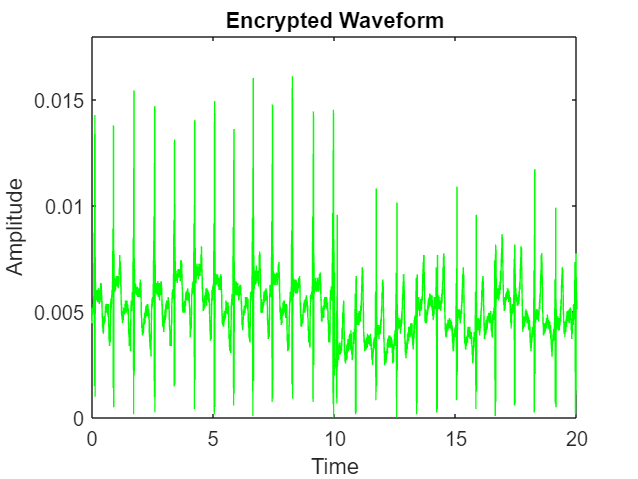

plot(t_enc,enc_col,'g')
xlabel("Time")
ylabel("Amplitude")
title("Encrypted Waveform")



%Decrypted Waveform
t_dec=(0:length(orig)-1)/fs

t_dec =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


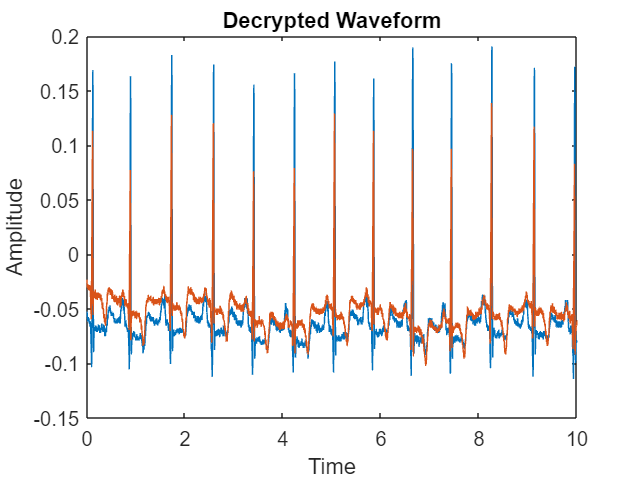

plot(t_dec,orig)
xlabel("Time")
ylabel("Amplitude")
title("Decrypted Waveform")

%Error Calculation
val1=abs(a_cut_mono)

val1 =     0.0527
    0.0537
    0.0557
    0.0586
    0.0586
    0.0615
    0.0596
    0.0586
    0.0576
    0.0586


val2=abs(dec)

val2 =     0.0527
    0.0537
    0.0557
    0.0586
    0.0586
    0.0615
    0.0596
    0.0586
    0.0576
    0.0586


error=val1-val2

error = 1.0e-12 *

    0.0424
    0.0433
    0.0448
    0.0472
    0.0472
    0.0495
    0.0479
    0.0472
    0.0462
    0.0472
